close all;
clear variables;

## Калибровка

calibzero_ = load('2-experimentData/calibzero.dat')

calibzero_ =     1.0000  483.9500
    2.0000  483.2750
    3.0000  483.5500
    4.0000  483.5000
    5.0000  483.2500
    6.0000  482.8250
    7.0000  481.2750
    8.0000  484.5750
    9.0000  483.5500
   10.0000  483.7000


calib_ = load('2-experimentData/calib.dat')

calib_ = 	1.0e+03 *

    0.0010    1.0314
    0.0020    1.0358
    0.0030    1.0357
    0.0040    1.0305
    0.0050    1.0365
    0.0060    1.0355
    0.0070    1.0337
    0.0080    1.0284
    0.0090    1.0341
    0.0100    1.0307



calibzero = calibzero_(:, 2)

calibzero =   483.9500
  483.2750
  483.5500
  483.5000
  483.2500
  482.8250
  481.2750
  484.5750
  483.5500
  483.7000


calib = calib_(:, 2)

calib = 	1.0e+03 *

    1.0314
    1.0358
    1.0357
    1.0305
    1.0365
    1.0355
    1.0337
    1.0284
    1.0341
    1.0307


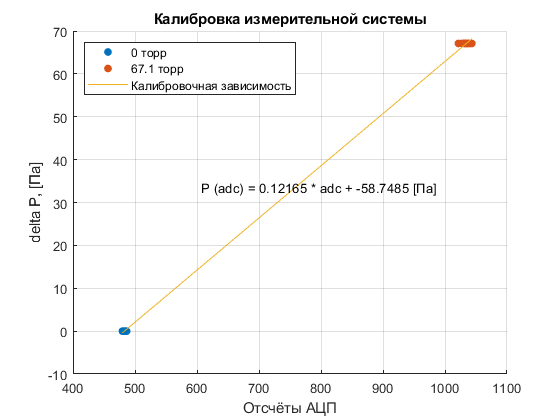


fclose('all');

torr0 = ones(length(calibzero), 1) * 0;
torr = ones(length(calib), 1) * 67.1;

cCalib = [calibzero; calib];
cTorr = [torr0; torr];

c = polyfit(cCalib, cTorr, 1);

cFigure = figure('Name', 'Калибровка', 'NumberTitle', 'off');
hold all;

plot(calibzero, torr0, '.', 'MarkerSize', 20);
plot(calib, torr, '.', 'MarkerSize', 20);

plot(cCalib, polyval(c, cCalib));

legend('0 торр', '67.1 торр', 'Калибровочная зависимость', 'Location', 'Northwest');

grid on;
xlabel('Отсчёты АЦП');
ylabel('delta P, [Па]');
title('Калибровка измерительной системы');
text(mean(cCalib) * 0.8, mean(cTorr), ['P (adc) = ', num2str(c(1)), ' * adc + ', num2str(c(2)), ' [Па]']);

saveas(cFigure, 'Калибровка.png');

## Загрузка данных

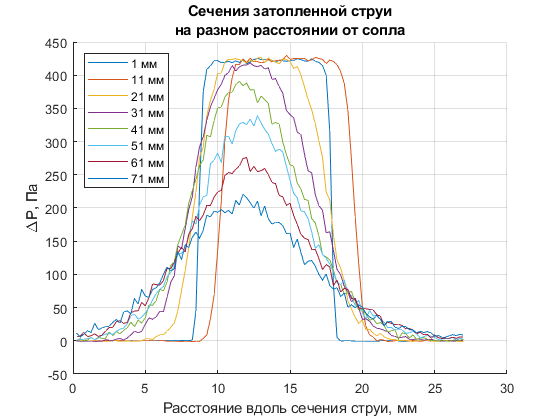


mm01 = load('2-experimentData/01mm.dat');
mm11 = load('2-experimentData/11mm.dat');
mm21 = load('2-experimentData/21mm.dat');
mm31 = load('2-experimentData/31mm.dat');
mm41 = load('2-experimentData/41mm.dat');
mm51 = load('2-experimentData/51mm.dat');
mm61 = load('2-experimentData/61mm.dat');
mm71 = load('2-experimentData/71mm.dat');

dx = 0.25; % мм
x = mm01(:, 1)' * 0.25;

p01 = polyval(c, mm01(:, 2));
p11 = polyval(c, mm11(:, 2));
p21 = polyval(c, mm21(:, 2));
p31 = polyval(c, mm31(:, 2));
p41 = polyval(c, mm41(:, 2));
p51 = polyval(c, mm51(:, 2));
p61 = polyval(c, mm61(:, 2));
p71 = polyval(c, mm71(:, 2));

pressure = [p01, p11, p21, p31, p41, p51, p61, p71];
zNames = {'1 мм'; '11 мм'; '21 мм'; '31 мм'; '41 мм'; '51 мм'; '61 мм'; '71 мм'};
z = [1, 11, 21, 31, 41, 51, 61, 71];

f2 = figure();
hold on;
grid on;
title({'Сечения затопленной струи', 'на разном расстоянии от сопла'});
ylabel('\DeltaP, Па');
xlabel('Расстояние вдоль сечения струи, мм');

for i = 1:size(pressure, 2)
    plot(x, pressure(:, i), 'DisplayName', zNames{i});
end

legend('Location', 'NorthWest');

saveas(f2, 'pressure.png');

## Сдвиг к центру сопла

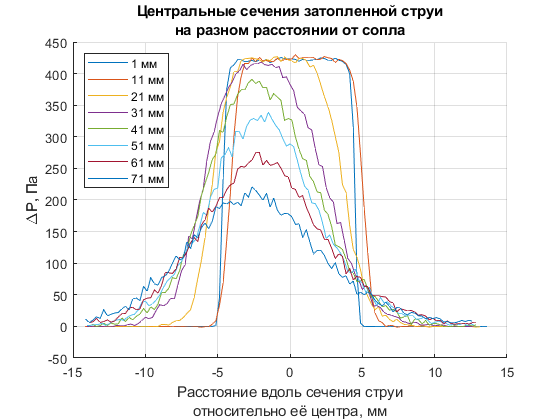

f3 = figure();
hold on;
grid on;
title({'Центральные сечения затопленной струи', 'на разном расстоянии от сопла'});
ylabel('\DeltaP, Па');
xlabel({'Расстояние вдоль сечения струи', 'относительно её центра, мм'});

xCentered = zeros(size(pressure));
offset = 50;

for i = 1:size(pressure, 2)
    right = x(find(pressure(:, i) > offset, 1, 'last'));
    left = x(find(pressure(:, 1) > offset, 1));
    
    center = left + (right - left) / 2;
    xCentered(:, i) = x - center;
    
    plot(xCentered(:, i), pressure(:, i), 'DisplayName', zNames{i});
end

legend('Location', 'Northwest');
hold off
saveas(f3, 'centered.png');

## Расчёт давления по формуле  Бернулли

Плотность воздуха при 20 градусов Цельсия и нормальном давлении:

ro = 1.204

ro = 1.2040

vitesse_2 = 2 * pressure /  ro

vitesse_2 =    -0.1089   -0.0078   -0.1089   -0.0685    0.7196    2.1745    9.5098   19.2295
   -0.8464   -0.4524   -0.1695   -1.1192    5.3067    3.0233   12.0155    9.6715
   -0.6141    0.8207   -0.5130   -0.6545   -0.2301    4.3569   20.4823   16.7642
   -0.7858   -0.5130   -0.7757   -0.7555    2.0937    4.7813   10.3383   25.0492
   -0.1089   -0.5736   -0.4928   -0.6141    8.2974    8.3984   12.6621   20.7450
   -0.1493    0.7398    0.0124   -1.3819    2.6999    2.5787   17.2088   44.0238
    0.1134    0.1134   -0.5130   -1.2203    8.6409    6.6606   11.0455   27.7368
   -0.6646   -0.3109   -1.0384   -0.8970    5.9937   13.2279   14.2383   32.0611
   -0.4019   -0.5534   -1.3011    2.6191    6.5191   16.7440   24.4834   34.8901
   -0.7050    0.5378   -0.6343    1.4875   22.6041   18.2595   33.0715   36.5269


vitesse_2(vitesse_2 < 0) = 0

vitesse_2 =          0         0         0         0    0.7196    2.1745    9.5098   19.2295
         0         0         0         0    5.3067    3.0233   12.0155    9.6715
         0    0.8207         0         0         0    4.3569   20.4823   16.7642
         0         0         0         0    2.0937    4.7813   10.3383   25.0492
         0         0         0         0    8.2974    8.3984   12.6621   20.7450
         0    0.7398    0.0124         0    2.6999    2.5787   17.2088   44.0238
    0.1134    0.1134         0         0    8.6409    6.6606   11.0455   27.7368
         0         0         0         0    5.9937   13.2279   14.2383   32.0611
         0         0         0    2.6191    6.5191   16.7440   24.4834   34.8901
         0    0.5378         0    1.4875   22.6041   18.2595   33.0715   36.5269


vitesse = sqrt(vitesse_2)

vitesse =          0         0         0         0    0.8483    1.4746    3.0838    4.3851
         0         0         0         0    2.3036    1.7388    3.4663    3.1099
         0    0.9059         0         0         0    2.0873    4.5257    4.0944
         0         0         0         0    1.4470    2.1866    3.2153    5.0049
         0         0         0         0    2.8805    2.8980    3.5584    4.5547
         0    0.8601    0.1112         0    1.6431    1.6058    4.1483    6.6350
    0.3368    0.3368         0         0    2.9395    2.5808    3.3235    5.2666
         0         0         0         0    2.4482    3.6370    3.7734    5.6623
         0         0         0    1.6184    2.5533    4.0919    4.9481    5.9068
         0    0.7333         0    1.2196    4.7544    4.2731    5.7508    6.0438


Тогда для графика:

f4 = surf(vitesse)

f4 =   Surface with properties:

       EdgeColor: [0 0 0]
       LineStyle: '-'
       FaceColor: 'flat'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [1 2 3 4 5 6 7 8]
           YData: [108×1 double]
           ZData: [108×8 double]
           CData: [108×8 double]

  Show all properties


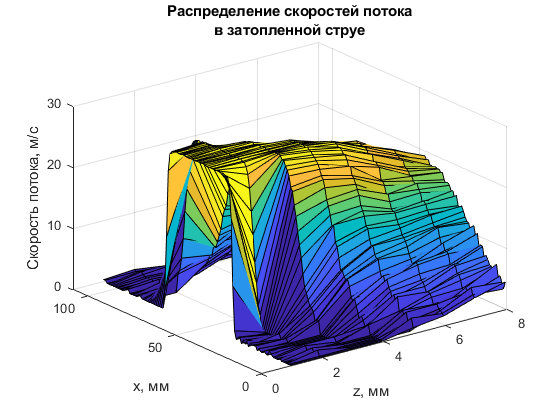

title({'Распределение скоростей потока', 'в затопленной струе'});
zlabel('Скорость потока, м/с')
ylabel('x, мм');
xlabel({'z, мм'});
saveas(f4, 'vitesse.png');

## Расход затопленной струи

flow = pi*0.03*0.03*cumtrapz(vitesse)

flow =          0         0         0         0         0         0         0         0
         0         0         0         0    0.0045    0.0045    0.0093    0.0106
         0    0.0013         0         0    0.0077    0.0100    0.0206    0.0208
         0    0.0026         0         0    0.0098    0.0160    0.0315    0.0336
         0    0.0026         0         0    0.0159    0.0232    0.0411    0.0472
         0    0.0038    0.0002         0    0.0223    0.0295    0.0520    0.0630
    0.0005    0.0055    0.0003         0    0.0287    0.0355    0.0625    0.0798
    0.0010    0.0059    0.0003         0    0.0364    0.0443    0.0726    0.0953
    0.0010    0.0059    0.0003    0.0023    0.0434    0.0552    0.0849    0.1116
    0.0010    0.0070    0.0003    0.0063    0.0538    0.0670    0.1000    0.1285




f5 = plot([1, 11, 21, 31, 41, 51, 61, 71], flow(108,:))

f5 =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1 11 21 31 41 51 61 71]
              YData: [2.8316 3.0126 3.3441 3.5842 3.6106 3.5457 3.4799 3.3281]
              ZData: [1×0 double]

  Show all properties


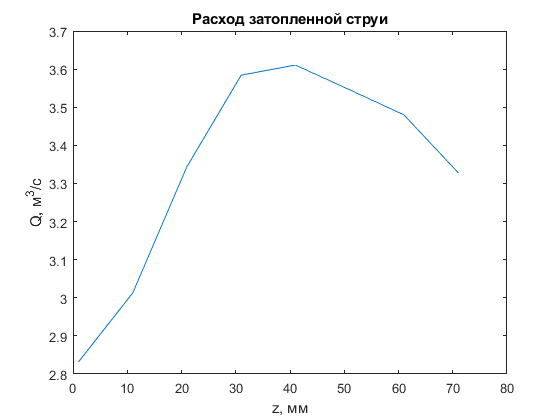

title('Расход затопленной струи')
ylabel('Q, м^3/с');
xlabel({'z, мм'});

saveas(f5, 'flow.png');